% (C) Copyright 2020-2023 Murilo Marques Marinho (murilomarinho@ieee.org)
%
%     This file is licensed in the terms of the
%     Attribution-NonCommercial-ShareAlike 4.0 International (CC BY-NC-SA 4.0) 
%     license.
%
% Contributors to this file:
%     Murilo Marques Marinho (murilomarinho@ieee.org)
clear all;
close all;

# Dual Quaternion Basics using DQ Robotics

## Introduction

Before introducing dual quaternions, it is common practice to introduce the concept of dual numbers. Let us start with that.

As always, let us add the namespace to our workspace.

%% Include the DQ Robotics namespace. Probably a good idea to add to all scripts.
include_namespace_dq

## Dual Numbers

The set of dual numbers $\mathbb{D}$ is yet a different way to extend $\mathbb{R}$. Any dual number can be written in the form


$$\underline{d} =a+b\varepsilon \;,$$


where $a,b\in \;$$\mathbb{R}$. The algebra of dual numbers is based on the following property of the nilpotent dual unit


$$\varepsilon \not= \;0,\varepsilon^2 =0\ldotp$$


For instance, the dual number


$${\underline{d} }_1 =10-239\varepsilon$$


can be written using DQ Robotics as follows.

d1 = 10 - 239*E_

d1 = 
         (10) + E*( - 239)


Note that the properties of the dual unit hold

E_

E_ = 
         E*(1)


E_*E_

ans = 
         0


## **Operations on dual numbers**

The operations on dual numbers are very similar to the operations on real numbers. We just need to respect the property $\varepsilon \not= \;0,\varepsilon^2 =0\ldotp$

For instance, for the dual numbers


$${\underline{d} }_1 =a_1 +{\varepsilon b}_1$$


${\underline{d} }_2 =a_2 +{\varepsilon b}_2$, 

d1 = 10 - 239*E_

d1 = 
         (10) + E*( - 239)


d2 = 55 + 32*E_

d2 = 
         (55) + E*(32)


## Sum/Subtraction


$${\underline{d} }_1 \pm \;{\underline{d} }_2 =\left(a_1 \pm \;a_2 \right)+\left(b_1 \pm \;b_2 \right)\varepsilon \ldotp$$


d1+d2

ans = 
         (65) + E*( - 207)


d1-d2

ans = 
         ( - 45) + E*( - 271)


## Product

In the dual number product, the nilpotent property of the dual unit shows.


$$\begin{array}{l}
{\underline{d} }_1 {\underline{d} }_2 =\left(a_1 a_2 \right)+\varepsilon \left(a_1 b_2 +a_2 b_1 \right)+\varepsilon^2 \left(b_1 b_2 \right)\\
\Rightarrow {\underline{d} }_1 {\underline{d} }_2 =\left(a_1 a_2 \right)+\varepsilon \left(a_1 b_2 +a_2 b_1 \right)
\end{array}$$


d1*d2

ans = 
         (550) + E*( - 12825)


## Primary part

The operator $P\left(\ldotp \right)$ can be used to obtain the primary part of the dual number. (The primary part is that which is not multiplied by the dual unit)


$$P\left(\underline{d} \right)=a$$


P(d1)

ans = 
         10


## **Dual part**

The operator $D\left(\ldotp \right)$ can be used to obtain the dual part of the dual number. (The dual number is that which is multiplied by the dual unit)


$$D\left(\underline{d} \right)=b$$


D(d1)

ans = 
          - 239


## **Dual quaternions**

When we extend the concept of dual numbers to be composed of two quaternions, we have what we call dual quaternions. They compose the set $\mathcal{H}$ and can always be written in the form 


$$\underline{\mathit{\mathbf{h}}} =\mathit{\mathbf{h}}+\grave{\mathit{\mathbf{h}}} \varepsilon$$


where $\mathit{\mathbf{h}},\grave{\mathit{\mathbf{h}}} \in \;$$\mathbb{H}$. 

Note that $\mathbb{R} \subset \mathcal{H}$, $\mathbb{C} \subset \mathcal{H}$, $\mathbb{H} \subset \mathcal{H}$, $\mathbb{D} \subset \mathcal{H}$. That is, the real numbers, the complex numbers, the quaternions, and the dual numbers are all subsets of dual quaternions. 

For instance, the dual quaternion


$${\underline{\mathit{\mathbf{h}}} }_1 =5+6\hat{\i \;} +7\hat{\;\j \;} +8\hat{\;k} +\varepsilon \left(9+15\hat{\i \;} +7\hat{\;\j \;} +8\hat{\;k} \right)$$
 

can be written using DQ Robotics as follows

h1 = 5 + 6*i_ + 7*j_ + 8*k_ + E_*(9 + 15*i_ + 7*j_ + 8*k_)

h1 = 
         (5 + 6i + 7j + 8k) + E*(9 + 15i + 7j + 8k)


## Operations on dual quaternions

Considering ${\underline{\mathit{\mathbf{h}}} }_1 ,{\underline{\mathit{\mathbf{h}}} }_2 \in \;$$\mathcal{H}$, for example

h1 = 5 + 6*i_ + 7*j_ + 8*k_ + E_*(9 + 15*i_ + 7*j_ + 8*k_)

h1 = 
         (5 + 6i + 7j + 8k) + E*(9 + 15i + 7j + 8k)


h2 = -25 + 1*k_ + E_*( 7*j_ + 8*k_)

h2 = 
         ( - 25 + 1k) + E*(7j + 8k)


## Sum/Subtraction


$${\underline{\mathit{\mathbf{h}}} }_1 \pm {\underline{\mathit{\mathbf{h}}} }_2 =\left({\mathit{\mathbf{h}}}_1 \pm {\mathit{\mathbf{h}}}_2 \right)+\varepsilon \left({\mathit{\mathbf{h}}}_1^{\prime } \pm {\mathit{\mathbf{h}}}_2^{\prime } \right)$$


h1+h2

ans = 
         ( - 20 + 6i + 7j + 9k) + E*(9 + 15i + 14j + 16k)


h1-h2

ans = 
         (30 + 6i + 7j + 7k) + E*(9 + 15i)


## **Multiplication**


$${\underline{\mathit{\mathbf{h}}} }_1 {\underline{\mathit{\mathbf{h}}} }_2 =\left({\mathit{\mathbf{h}}}_1 {\mathit{\mathbf{h}}}_2 \right)+\varepsilon \left({\mathit{\mathbf{h}}}_1 {\mathit{\mathbf{h}}}_2^{\prime } +{\mathit{\mathbf{h}}}_2 {\mathit{\mathbf{h}}}_1^{\prime } \right)$$


h1*h2

ans = 
         ( - 133 - 143i - 181j - 195k) + E*( - 346 - 368i - 203j - 109k)


Notice that the multiplication between dual quaternions is, ***in general***, NOT COMMUTATIVE.


$${\mathit{\mathbf{h}}}_1 {\mathit{\mathbf{h}}}_2 \not= {{\mathit{\mathbf{h}}}_2 \mathit{\mathbf{h}}}_1$$


h3 = h1*h2 

h3 = 
         ( - 133 - 143i - 181j - 195k) + E*( - 346 - 368i - 203j - 109k)


h4 = h2*h1

h4 = 
         ( - 133 - 157i - 169j - 195k) + E*( - 346 - 382i - 77j - 193k)


if h3==h4
    disp('h1*h2 is equal to h2*h1')
else 
    disp('h1*h2 is not equal to h2*h1')
end

h1*h2 is not equal to h2*h1


## Conjugation

The conjugate of the dual quaternion is obtained by taking the conjugate of the primary part and the dual part of the dual quaternion. Both of which are quaternions. This same logic applies for many other operators.


$${\left({\underline{\mathit{\mathbf{h}}} }_1 \right)}^* ={\left({\mathit{\mathbf{h}}}_1 \right)}^* +{\varepsilon \left({\mathit{\mathbf{h}}}_1^{\prime } \right)}^*$$


conj(h1)

ans = 
         (5 - 6i - 7j - 8k) + E*(9 - 15i - 7j - 8k)


**Norm**


$$\left|\right|{\underline{\mathit{\mathbf{h}}} }_1 \left|\right|=\sqrt{{\underline{\mathit{\mathbf{h}}} }_1 {\left({\underline{\mathit{\mathbf{h}}} }_1 \right)}^* \;}$$


norm(h1)

ans = 
         (13.1909) + E*(18.8008)


## Real part


$$\textrm{Re}\left({\underline{\mathit{\mathbf{h}}} }_1 \right)=\textrm{Re}\left({\mathit{\mathbf{h}}}_1 \right)+\epsilon \textrm{Re}\left({\mathit{\mathbf{h}}}_1^{\prime } \right)$$


Re(h1)

ans = 
         (5) + E*(9)


If the real part of a dual quaternion is zero, it is called a *pure dual quaternion*, and belongs to the set $\mathcal{H}_p$.

## Imaginary part


$$\textrm{Im}\left({\underline{\mathit{\mathbf{h}}} }_1 \right)=\textrm{Im}\left({\mathit{\mathbf{h}}}_1 \right)+\epsilon \textrm{Im}\left({\mathit{\mathbf{h}}}_1^{\prime } \right)$$


Im(h1)

ans = 
         (6i + 7j + 8k) + E*(15i + 7j + 8k)


If the imaginary part of a dual quaternion is zero, it is a dual number.

## Primary part


$$P\left({\underline{\mathit{\mathbf{h}}} }_1 \right)={\mathit{\mathbf{h}}}_1$$


P(h1)

ans = 
         5 + 6i + 7j + 8k


## **Dual part**


$$D\left({\underline{\mathit{\mathbf{h}}} }_1 \right)={\mathit{\mathbf{h}}}_1^{\prime }$$


D(h1)

ans = 
         9 + 15i + 7j + 8k


## Vec6

The imaginary part of dual quaternions can be mapped to $\mathbb{R}^6$ as follows


$${\textrm{vec}}_6 \left({\underline{\mathit{\mathbf{h}}} }_1 \right)=\left\lbrack \begin{array}{c}
{\textrm{vec}}_3 \left({\mathit{\mathbf{h}}}_1 \right)\\
{\textrm{vec}}_3 \left({\mathit{\mathbf{h}}}_1^{\prime } \right)
\end{array}\right\rbrack$$


vec6(h1)

ans =      6
     7
     8
    15
     7
     8


## Vec8

Quaternions can be mapped to $\mathbb{R}^8$ as follows


$${\textrm{vec}}_4 \left({\underline{\mathit{\mathbf{h}}} }_1 \right)=\left\lbrack \begin{array}{c}
{\textrm{vec}}_4 \left({\mathit{\mathbf{h}}}_1 \right)\\
{\textrm{vec}}_4 \left({\mathit{\mathbf{h}}}_1^{\prime } \right)
\end{array}\right\rbrack$$


vec8(h1)

ans =      5
     6
     7
     8
     9
    15
     7
     8


## Hamilton Operators

The hamilton operators are useful to provide a form of commutativity in the dual quaternion multiplication.


$${\textrm{vec}}_8 \left({\underline{\mathit{\mathbf{h}}} }_1 {\underline{\mathit{\mathbf{h}}} }_2 \right)=\overset{+}{{\mathit{\mathbf{H}}}_8 } \left({\underline{\mathit{\mathbf{h}}} }_1 \right){\textrm{vec}}_8 \left({\underline{\mathit{\mathbf{h}}} }_2 \right)=\overset{-}{{\mathit{\mathbf{H}}}_8 } \left({\underline{\mathit{\mathbf{h}}} }_2 \right){\textrm{vec}}_8 \left({\underline{\mathit{\mathbf{h}}} }_1 \right)$$


vec8(h1*h2)

ans =   -133
  -143
  -181
  -195
  -346
  -368
  -203
  -109


hamiplus8(h1)*vec8(h2)

ans =   -133
  -143
  -181
  -195
  -346
  -368
  -203
  -109


haminus8(h2)*vec8(h1)

ans =   -133
  -143
  -181
  -195
  -346
  -368
  -203
  -109


## Unit Dual Quaternions motion of rigid bodies

Unit dual quaternions compose the set $\underline{\bf{\mathcal{S}}}$, which represent pose transformations of the reference frame of rigid bodies in three dimensional space. 

A unit dual quaternion representing a translation followed by a rotation can always be written in the form


$$\underline{\mathit{\mathbf{x}}} =\mathit{\mathbf{r}}+\varepsilon \frac{\;1}{2}\mathit{\mathbf{t}}\ldotp \mathit{\mathbf{r}}$$


where $\mathit{\mathbf{r}}\in$$\mathbb{S}^3$ is the unit-norm quaternion representing the rotation; and $\bf{t}$ $\in \mathbb{H}_p$ is the quaternion representing the translation. 

Remember this nomenclature:

- $\bf{t}$ $\in \mathbb{H}_p$ is a translation.

- $\mathit{\mathbf{r}}\in$$\mathbb{S}^3$ is a rotation.

- $\underline{\mathit{\mathbf{x}}}$ $\in$$\underline{\bf{\mathcal{S}}}$ is a pose transformation (combined translation and rotation).

Unit-norm dual-quaternions, as the name says, have unit norm


$$\left|\right|\underline{\mathit{\mathbf{x}}} \left|\right|=1\ldotp$$


For instance, to represent the translation of 1 meter about the y-axis,


$${\mathit{\mathbf{t}}}_1 =\hat{\;\j \;\;} ,$$


t1 = j_

t1 = 
         1j


followed by a rotation of $\frac{\pi }{2}$ rad about the x-axis,


$$r_1 =\cos \left(\frac{\;\pi \;}{4}\right)+\hat{\;\i \;} \sin \left(\frac{\pi \;}{4}\right)$$


r1 = cos(pi/4) + i_*sin(pi/4)

r1 = 
         0.70711 + 0.70711i


the pose transformation will be


$${\underline{\;\mathit{\mathbf{x}}} }_1 ={\mathit{\mathbf{r}}}_1 +\varepsilon \frac{\;1}{2}{\mathit{\mathbf{t}}}_1 {\mathit{\mathbf{r}}}_1 =\cos \left(\frac{\;\pi \;}{4}\right)+\hat{\;\i \;} \sin \left(\frac{\;\pi \;}{4}\right)+\frac{\;1}{2}\varepsilon \left(\hat{\;\j \;\;} \cos \left(\frac{\;\pi \;}{4}\right)-\hat{\;k\;} \sin \left(\frac{\;\pi \;}{4}\right)\right)$$


x1 = r1 + 0.5*E_*t1*r1

x1 = 
         (0.70711 + 0.70711i) + E*(0.35355j - 0.35355k)


We can check that ${\underline{\;\mathit{\mathbf{x}}} }_1$ indeed has unit norm 

norm(x1)

ans = 
         1


## Dual quaternion double-cover property

Given the way that the pose transformation is based on quaternions, the double cover also extends to dual quaternions.


$${\underline{\;\mathit{\mathbf{x}}} }_1$$


and


$$-{\underline{\;\mathit{\mathbf{x}}} }_1$$


represent the same pose transformation.

## No pose transformation

The dual quaternion that represents that there is no pose transformation is


$${\underline{\;\mathit{\mathbf{x}}} }_1 =1$$


x1 = DQ(1)

x1 = 
         1


## Plotting unit dual quaternions

Using DQ Robotics, unit dual quaternions can be plotted on screen the same way as unit quaternions.

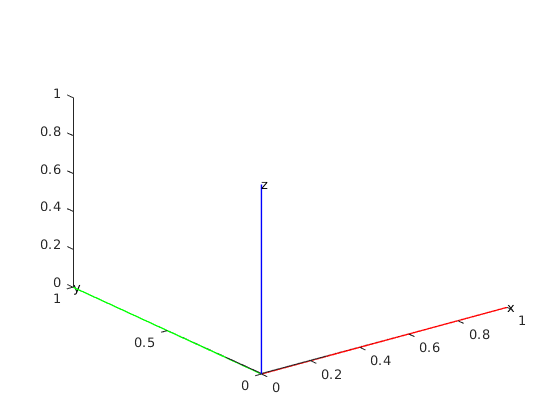

plot(x1);

## Sequential pose transforrmations

Sequential pose transformations are obtained by post-multiplication of unit dual quaternions. For example, the transformation between the neutral reference frame by ${\underline{\;\mathit{\mathbf{x}}} }_1$ followed by ${\underline{\;\mathit{\mathbf{x}}} }_2$  is 


$${\underline{\;\mathit{\mathbf{x}}} }_3 ={\underline{\;\mathit{\mathbf{x}}} }_1 {\underline{\;\mathit{\mathbf{x}}} }_2$$


disp('Sequential pose transformations')

Sequential pose transformations


%% Define the initial pose
t1 = 0;
r1 = 1;
x1 = r1 + 0.5*E_*t1*r1

x1 = 
         1



%% Define the second pose transformation
t2 = j_;
r2 = cos(pi/4) + i_*sin(pi/4);
x2 = r2 + 0.5*E_*t2*r2

x2 = 
         (0.70711 + 0.70711i) + E*(0.35355j - 0.35355k)



%% Define the third pose transformation
t3 = -k_ + 2*i_;
r3 = cos(pi/32) + k_*sin(pi/32);
x3 = r3 + 0.5*E_*t3*r3

x3 = 
         (0.99518 + 0.098017k) + E*(0.049009 + 0.99518i - 0.098017j - 0.49759k)



%% Plot using subplot
subplot(1,3,1);
plot(x1);
title('x1');

subplot(1,3,2);
plot(x1*x2);
title('x1*x2');
x1*x2

ans = 
         (0.70711 + 0.70711i) + E*(0.35355j - 0.35355k)


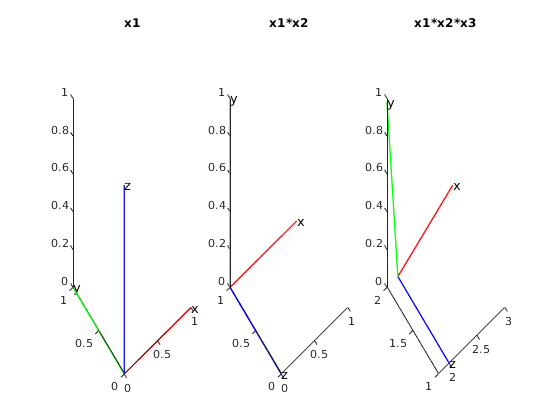


subplot(1,3,3);
plot(x1*x2*x3);
title('x1*x2*x3');

x1*x2*x3

ans = 
         (0.7037 + 0.7037i - 0.069309j + 0.069309k) + E*( - 0.63439 + 0.77301i + 0.63439j - 0.77301k)


## Reverse pose transformation

The reverse pose transformation can be obtained using the conjugate operation, because unit dual quaternions have unit norm. Hence, 


$$\underline{\mathit{\mathbf{x}}} {\left(\underline{\;\mathit{\mathbf{x}}} \right)}^* =1$$


for any unit dual quaternion.

For example,

x3

x3 = 
         (0.99518 + 0.098017k) + E*(0.049009 + 0.99518i - 0.098017j - 0.49759k)


x3*conj(x3)

ans = 
         1


## Rotation

The operator $\textrm{rotation}\left(\ldotp \right)$ can be used to retrieve the rotation represented by a unit dual quaternion.

rotation(x3)

ans = 
         0.99518 + 0.098017k


## Translation

The operator $\textrm{translation}\left(\ldotp \right)$ can be used to retrive the translation represented by a unit dual quaternion.

translation(x3)

ans = 
         2i - 1k


# Homework

Following the template above to create a script called [dual_quaternion_basics_homework_part1.m], do the following.

- Store, in ${\underline{\mathit{\mathbf{x}}} }_1$, the pose transformation of a translation of 1 meter in the x-axis, followed by a rotation of $\frac{\;\pi \;}{8}$ rad about the z-axis.

- Store, in ${\underline{\mathit{\mathbf{x}}} }_2$, the pose transformation of a translation of -1 meter in the z-axis, followed by a rotation of $-\frac{\;\pi \;}{2}$ rad about the x-axis.

- Calculate the result of the sequential rotation of the neutral reference-frame by ${\underline{\mathit{\mathbf{x}}} }_0 =1$, followed by ${\underline{\mathit{\mathbf{x}}} }_1$, followed by ${\underline{\mathit{\mathbf{x}}} }_2$, and store it in ${\underline{\mathit{\mathbf{x}}} }_3$. Plot ${\underline{\mathit{\mathbf{x}}} }_3$.

- Obtain the rotation of ${\underline{\mathit{\mathbf{x}}} }_3$ without using $\textrm{rotation}\left(\ldotp \right)$

- Obtain the translation of ${\underline{\mathit{\mathbf{x}}} }_3$ without using $\textrm{translation}\left(\ldotp \right)$

- Obtain the pose transformation of a rotation of $\frac{\;\pi \;}{8}$ rad about the z-axis followed by a translation of 1 meter in the x-axis, and store it in ${\underline{\mathit{\mathbf{x}}} }_4$. Is it the same as ${\underline{\mathit{\mathbf{x}}} }_1$? If it is different, why is it different?